# Reto F3001C

Max Eduardo Garcia Esquivel - A01236070.

   %Code Variables
%Sizes
sXs = [1000,930,475,405];
sYs = [325,235,955,730];

%Paths
SuperiorPath = "./../Phase4V2/Sweeps/Matlab/";
FundamentalPath = "./../Phase3/Sweeps/Matlab/";

%Modes
Superior = "Waveguide%i_%i_532_Mode%i";
Fundamental = "Waveguide%i_%i_1596";
ModesSup = [15,9,19,12];

warning('off','MATLAB:polyfit:RepeatedPointsOrRescale')

## Waveguide selector:

sel = 4;
nmodes = ModesSup(sel);
mode = 2;
disp("Selected waveguide:")

Selected waveguide:


disp("   Size: "+num2str(sXs(sel))+"x"+num2str(sYs(sel)));

   Size: 405x730


disp("   Mode: "+num2str(mode));

   Mode: 12


## Waveguide Summary:

disp("Waveguide: "+num2str(sXs(sel))+"x"+num2str(sXs(sel))+", mode: "+num2str(ModesSup(sel)));

Waveguide: 405x405, mode: 12


### Fundamental Mode Data (1596nm):

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
l = wgFundamental.lambdaData;
w = wgFundamental.omegaData;
neff = wgFundamental.neffData;

#### Ranges:

disp("Lambda Ranges: "+num2str(min(l))+"-"+num2str(max(l))+"");

Lambda Ranges: 1.53-1.596


disp("Omega Ranges: "+num2str(min(w))+"-"+num2str(max(w))+"");

Omega Ranges: 1181049869.7706-1231997119.0548


#### Neff vs ω/λ

disp("Function neff(λ):");

Function neff(λ):


disp(wgFundamental.nefflStr);

-0.000032618120069393180993251591*l.^30+0.000160183850449802019652936758*l.^29-0.000165516382843027400149221728*l.^28+0.000123367479808266455008902707*l.^27-0.001079813963634779824113385516*l.^26-0.000627247332070214364159455034*l.^25+0.007577263162713798044789470509*l.^24-0.002430614033654377240112332004*l.^23-0.005862734450360423954506927657*l.^22-0.014369754604447441959091946728*l.^21+0.000324231022713570952997752528*l.^20+0.028977352701403912005329033263*l.^19+0.002988857072600976157866758953*l.^18+0.110752969766493708503318771363*l.^17-0.154349556235825274841388932145*l.^16-0.188367910467289234599519431868*l.^15+0.244557875608663155553301749023*l.^14-0.341540325370606356880642806573*l.^13+1.723949595140579438279360147135*l.^12-3.349538858267425034398456773488*l.^11+3.045574019248829422679136769148*l.^10-3.269128464746329676415825815639*l.^9+2.158492375692808717957404951449*l.^8+14.051066619358383746885010623373*l.^7-26.419759124777854708554514218122*l.^6+15.91658222153421320399502

disp("Function neff(ω)");

Function neff(ω)


disp(wgFundamental.neffwStr);

1.747346577041554230953220300498e-271*w.^30-7.662539294564936012074625087400e-262*w.^29+8.257018736675902781497804718224e-253*w.^28+2.669473384821174201813259841704e-244*w.^27+2.193041368864137404733202705061e-236*w.^26-8.940827686764131548596669942803e-226*w.^25-5.857976511342592374212689872426e-217*w.^24-4.988358110359949136948933016894e-208*w.^23+2.649650062776025664676871965943e-198*w.^22+2.283121868201802535725697496222e-189*w.^21-1.056327914254429827285507058955e-179*w.^20+1.178129489290512764762912325402e-170*w.^19-2.973881552022496836483306172895e-162*w.^18+5.979636339334658271062389759799e-153*w.^17-1.547037965972146083938357252763e-143*w.^16+1.093331081470451913014707983925e-134*w.^15-1.818124535762064562123337783750e-125*w.^14+3.442427219014576875852785241444e-118*w.^13-1.877729820907521690837530015748e-108*w.^12+9.377116337288823285423793482725e-98*w.^11-4.372219495987151156188380689827e-89*w.^10-1.098946165002371204298987336769e-79*w.^9+7.643257945693533996281649184361e-71

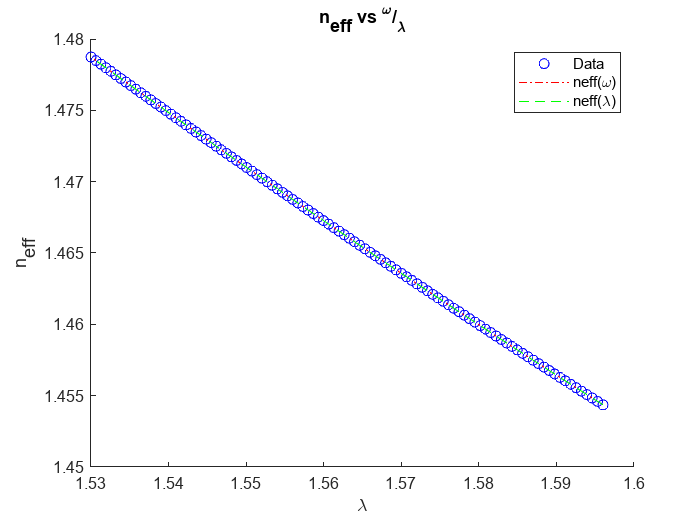

figure;
hold on
title("n_{eff} vs ^{\omega}/_{\lambda}");
plot(l,neff,'bo',l,wgFundamental.neffwFun(w),'r-.',l,wgFundamental.nefflFun(l),'g--');
legend(["Data","neff(\omega)","neff(\lambda)"]);
xlabel("\lambda");
ylabel("n_{eff}");
hold off

#### Subfunctions (k, dw, Vg, d2w, D)

disp("Function k(ω):");

Function k(ω):


disp(wgFundamental.kwStr);

w.*(1.747346577041554230953220300498e-271*w.^30-7.662539294564936012074625087400e-262*w.^29+8.257018736675902781497804718224e-253*w.^28+2.669473384821174201813259841704e-244*w.^27+2.193041368864137404733202705061e-236*w.^26-8.940827686764131548596669942803e-226*w.^25-5.857976511342592374212689872426e-217*w.^24-4.988358110359949136948933016894e-208*w.^23+2.649650062776025664676871965943e-198*w.^22+2.283121868201802535725697496222e-189*w.^21-1.056327914254429827285507058955e-179*w.^20+1.178129489290512764762912325402e-170*w.^19-2.973881552022496836483306172895e-162*w.^18+5.979636339334658271062389759799e-153*w.^17-1.547037965972146083938357252763e-143*w.^16+1.093331081470451913014707983925e-134*w.^15-1.818124535762064562123337783750e-125*w.^14+3.442427219014576875852785241444e-118*w.^13-1.877729820907521690837530015748e-108*w.^12+9.377116337288823285423793482725e-98*w.^11-4.372219495987151156188380689827e-89*w.^10-1.098946165002371204298987336769e-79*w.^9+7.643257945693533996281649184361

disp("Function dk(ω)/dω:");

Function dk(ω)/dω:


disp(wgFundamental.dkwdwStr);

(1.747346577041554230953220300498e-271*w.^30*(31)-7.662539294564936012074625087400e-262*w.^29*(30)+8.257018736675902781497804718224e-253*w.^28*(29)+2.669473384821174201813259841704e-244*w.^27*(28)+2.193041368864137404733202705061e-236*w.^26*(27)-8.940827686764131548596669942803e-226*w.^25*(26)-5.857976511342592374212689872426e-217*w.^24*(25)-4.988358110359949136948933016894e-208*w.^23*(24)+2.649650062776025664676871965943e-198*w.^22*(23)+2.283121868201802535725697496222e-189*w.^21*(22)-1.056327914254429827285507058955e-179*w.^20*(21)+1.178129489290512764762912325402e-170*w.^19*(20)-2.973881552022496836483306172895e-162*w.^18*(19)+5.979636339334658271062389759799e-153*w.^17*(18)-1.547037965972146083938357252763e-143*w.^16*(17)+1.093331081470451913014707983925e-134*w.^15*(16)-1.818124535762064562123337783750e-125*w.^14*(15)+3.442427219014576875852785241444e-118*w.^13*(14)-1.877729820907521690837530015748e-108*w.^12*(13)+9.377116337288823285423793482725e-98*w.^11*(12)-4.372219495987151156

disp("Function Vg(ω):");

Function Vg(ω):


disp(wgFundamental.vgwStr);

(3*10^8)./(1.747346577041554230953220300498e-271*w.^30*(31)-7.662539294564936012074625087400e-262*w.^29*(30)+8.257018736675902781497804718224e-253*w.^28*(29)+2.669473384821174201813259841704e-244*w.^27*(28)+2.193041368864137404733202705061e-236*w.^26*(27)-8.940827686764131548596669942803e-226*w.^25*(26)-5.857976511342592374212689872426e-217*w.^24*(25)-4.988358110359949136948933016894e-208*w.^23*(24)+2.649650062776025664676871965943e-198*w.^22*(23)+2.283121868201802535725697496222e-189*w.^21*(22)-1.056327914254429827285507058955e-179*w.^20*(21)+1.178129489290512764762912325402e-170*w.^19*(20)-2.973881552022496836483306172895e-162*w.^18*(19)+5.979636339334658271062389759799e-153*w.^17*(18)-1.547037965972146083938357252763e-143*w.^16*(17)+1.093331081470451913014707983925e-134*w.^15*(16)-1.818124535762064562123337783750e-125*w.^14*(15)+3.442427219014576875852785241444e-118*w.^13*(14)-1.877729820907521690837530015748e-108*w.^12*(13)+9.377116337288823285423793482725e-98*w.^11*(12)-4.37221949

disp("Function d2k(ω)/dω:");

Function d2k(ω)/dω:


disp(wgFundamental.d2kwdw2Str);

(1.747346577041554230953220300498e-271*w.^29*(930)-7.662539294564936012074625087400e-262*w.^28*(870)+8.257018736675902781497804718224e-253*w.^27*(812)+2.669473384821174201813259841704e-244*w.^26*(756)+2.193041368864137404733202705061e-236*w.^25*(702)-8.940827686764131548596669942803e-226*w.^24*(650)-5.857976511342592374212689872426e-217*w.^23*(600)-4.988358110359949136948933016894e-208*w.^22*(552)+2.649650062776025664676871965943e-198*w.^21*(506)+2.283121868201802535725697496222e-189*w.^20*(462)-1.056327914254429827285507058955e-179*w.^19*(420)+1.178129489290512764762912325402e-170*w.^18*(380)-2.973881552022496836483306172895e-162*w.^17*(342)+5.979636339334658271062389759799e-153*w.^16*(306)-1.547037965972146083938357252763e-143*w.^15*(272)+1.093331081470451913014707983925e-134*w.^14*(240)-1.818124535762064562123337783750e-125*w.^13*(210)+3.442427219014576875852785241444e-118*w.^12*(182)-1.877729820907521690837530015748e-108*w.^11*(156)+9.377116337288823285423793482725e-98*w.^10*(132)-

disp("Function D(ω):");

Function D(ω):


disp(wgFundamental.DwStr);

-(w.^2/(2*pi*3*10^8)).*((1.747346577041554230953220300498e-271*w.^29*(930)-7.662539294564936012074625087400e-262*w.^28*(870)+8.257018736675902781497804718224e-253*w.^27*(812)+2.669473384821174201813259841704e-244*w.^26*(756)+2.193041368864137404733202705061e-236*w.^25*(702)-8.940827686764131548596669942803e-226*w.^24*(650)-5.857976511342592374212689872426e-217*w.^23*(600)-4.988358110359949136948933016894e-208*w.^22*(552)+2.649650062776025664676871965943e-198*w.^21*(506)+2.283121868201802535725697496222e-189*w.^20*(462)-1.056327914254429827285507058955e-179*w.^19*(420)+1.178129489290512764762912325402e-170*w.^18*(380)-2.973881552022496836483306172895e-162*w.^17*(342)+5.979636339334658271062389759799e-153*w.^16*(306)-1.547037965972146083938357252763e-143*w.^15*(272)+1.093331081470451913014707983925e-134*w.^14*(240)-1.818124535762064562123337783750e-125*w.^13*(210)+3.442427219014576875852785241444e-118*w.^12*(182)-1.877729820907521690837530015748e-108*w.^11*(156)+9.37711633728882328542379

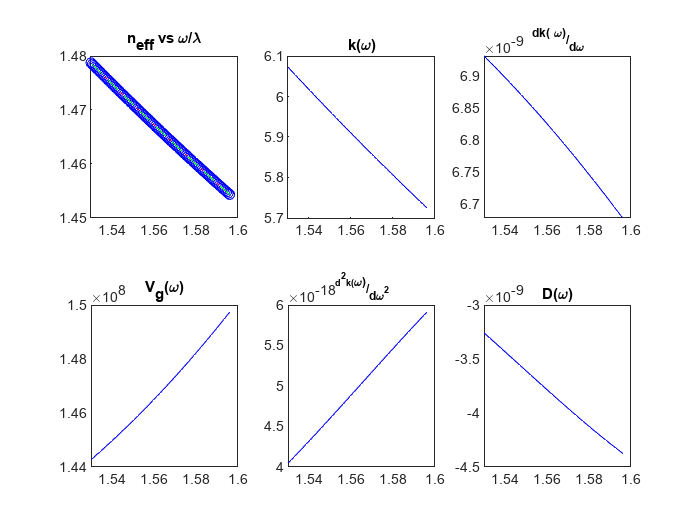

subplot(2,3,1);
plot(l,neff,'bo',l,wgFundamental.neffwFun(w),'r-.',l,wgFundamental.nefflFun(l),'g--');
title("n_{eff} vs \omega/\lambda");
subplot(2,3,2);
plot(l,wgFundamental.kwFun(w),'b');
title("k(\omega)");
subplot(2,3,3);
plot(l,wgFundamental.dkwdwFun(w),'b');
title("^{dk(\omega)}/_{d\omega}");
subplot(2,3,4);
plot(l,wgFundamental.vgwFun(w),'b');
title("V_g(\omega)");
subplot(2,3,5);
plot(l,wgFundamental.d2kwdw2Fun(w),'b');
title("^{d^2k(\omega)}/_{d\omega^2}");
subplot(2,3,6);
plot(l,wgFundamental.DwFun(w),'b');
title("D(\omega)");

### Superior Mode Data (530nm):

file = sprintf(Superior,sXs(sel),sYs(sel),ModesSup(sel));
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);
l = wgSuperior.lambdaData;
w = wgSuperior.omegaData;
neff = wgSuperior.neffData;

#### Ranges:

disp("Lambda Ranges: "+num2str(min(l))+"-"+num2str(max(l))+"");

Lambda Ranges: 0.51-0.532


disp("Omega Ranges: "+num2str(min(w))+"-"+num2str(max(w))+"");

Omega Ranges: 3543149609.3118-3695991357.1645


#### Neff vs ω/λ

disp("Function neff(λ):");

Function neff(λ):


disp(wgSuperior.nefflStr);

-5742622197979.337890625000000000000000000000*l.^30+17180000718023.595703125000000000000000000000*l.^29-19817629871182.417968750000000000000000000000*l.^28+11648426374100.021484375000000000000000000000*l.^27-3456857775923.082519531250000000000000000000*l.^26-1368407445267.792480468750000000000000000000*l.^25+2236293865165.242675781250000000000000000000*l.^24-292220541232.542785644531250000000000000000*l.^23-532806754942.450073242187500000000000000000*l.^22+69667066236.431640625000000000000000000000*l.^21+39661163983.136909484863281250000000000000*l.^20+60600666016.369194030761718750000000000000*l.^19-43497763261.620147705078125000000000000000*l.^18+14615635912.581159591674804687500000000000*l.^17-1700610282.476098060607910156250000000000*l.^16-2268071838.552524566650390625000000000000*l.^15-3154627.990193204022943973541259765625*l.^14+440532032.562427043914794921875000000000*l.^13-300014742.920106470584869384765625000000*l.^12+350686260.292585909366607666015625000000*l.^11-30950594.462

disp("Function neff(ω):");

Function neff(ω):


disp(wgSuperior.neffwStr);

8.372027009427822824801653302857e-283*w.^30-8.775337957019159296477410024564e-273*w.^29+2.733287150569474210475034892101e-263*w.^28-3.858339016773276206371723764696e-254*w.^27-6.645386904012222692712030874572e-244*w.^26+6.902691186264396945990722520929e-234*w.^25-1.010009223508927772493998941763e-225*w.^24-7.873798755086424049724118178109e-215*w.^23-1.804483211779327071749181596917e-205*w.^22+6.537746681543376330114501302530e-196*w.^21+4.730884863291634234709742261054e-187*w.^20+8.409290668099523355208779261980e-177*w.^19+3.591386000301386228570582489471e-167*w.^18-1.258281813432490933208074225859e-157*w.^17-5.919556113514044676157038062000e-148*w.^16+3.877418023806556818026438461221e-140*w.^15-1.902158236604748010333625844819e-130*w.^14+1.191942548585780591265141621184e-119*w.^13+9.463578001973747498457770579717e-111*w.^12+4.644726884650585617538786629229e-101*w.^11+3.113277641112150290005700572811e-91*w.^10+6.322443003914504561741061813370e-82*w.^9-9.249078491657299482930629890741e-7

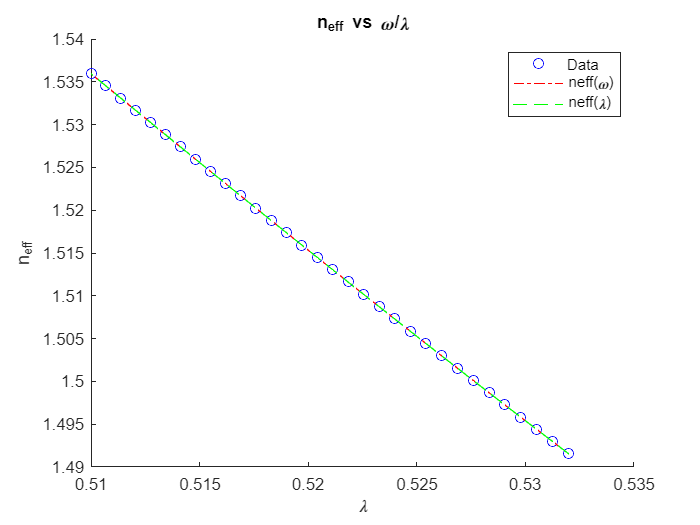

figure;
hold on
title("n_{eff} vs \omega/\lambda");
plot(l,neff,'bo',l,wgSuperior.neffwFun(w),'r-.',l,wgSuperior.nefflFun(l),'g--');
legend(["Data","neff(\omega)","neff(\lambda)"]);
xlabel("\lambda");
ylabel("n_{eff}");
hold off

#### Subfunctions (k, dw, Vg, d2w, D)

disp("Function k(ω):");

Function k(ω):


disp(wgSuperior.kwStr);

w.*(8.372027009427822824801653302857e-283*w.^30-8.775337957019159296477410024564e-273*w.^29+2.733287150569474210475034892101e-263*w.^28-3.858339016773276206371723764696e-254*w.^27-6.645386904012222692712030874572e-244*w.^26+6.902691186264396945990722520929e-234*w.^25-1.010009223508927772493998941763e-225*w.^24-7.873798755086424049724118178109e-215*w.^23-1.804483211779327071749181596917e-205*w.^22+6.537746681543376330114501302530e-196*w.^21+4.730884863291634234709742261054e-187*w.^20+8.409290668099523355208779261980e-177*w.^19+3.591386000301386228570582489471e-167*w.^18-1.258281813432490933208074225859e-157*w.^17-5.919556113514044676157038062000e-148*w.^16+3.877418023806556818026438461221e-140*w.^15-1.902158236604748010333625844819e-130*w.^14+1.191942548585780591265141621184e-119*w.^13+9.463578001973747498457770579717e-111*w.^12+4.644726884650585617538786629229e-101*w.^11+3.113277641112150290005700572811e-91*w.^10+6.322443003914504561741061813370e-82*w.^9-9.24907849165729948293062989074

disp("Function dk(ω)/dω:");

Function dk(ω)/dω:


disp(wgSuperior.dkwdwStr);

(8.372027009427822824801653302857e-283*w.^30*(31)-8.775337957019159296477410024564e-273*w.^29*(30)+2.733287150569474210475034892101e-263*w.^28*(29)-3.858339016773276206371723764696e-254*w.^27*(28)-6.645386904012222692712030874572e-244*w.^26*(27)+6.902691186264396945990722520929e-234*w.^25*(26)-1.010009223508927772493998941763e-225*w.^24*(25)-7.873798755086424049724118178109e-215*w.^23*(24)-1.804483211779327071749181596917e-205*w.^22*(23)+6.537746681543376330114501302530e-196*w.^21*(22)+4.730884863291634234709742261054e-187*w.^20*(21)+8.409290668099523355208779261980e-177*w.^19*(20)+3.591386000301386228570582489471e-167*w.^18*(19)-1.258281813432490933208074225859e-157*w.^17*(18)-5.919556113514044676157038062000e-148*w.^16*(17)+3.877418023806556818026438461221e-140*w.^15*(16)-1.902158236604748010333625844819e-130*w.^14*(15)+1.191942548585780591265141621184e-119*w.^13*(14)+9.463578001973747498457770579717e-111*w.^12*(13)+4.644726884650585617538786629229e-101*w.^11*(12)+3.11327764111215029

disp("Function Vg(ω):");

Function Vg(ω):


disp(wgSuperior.vgwStr);

(3*10^8)./(8.372027009427822824801653302857e-283*w.^30*(31)-8.775337957019159296477410024564e-273*w.^29*(30)+2.733287150569474210475034892101e-263*w.^28*(29)-3.858339016773276206371723764696e-254*w.^27*(28)-6.645386904012222692712030874572e-244*w.^26*(27)+6.902691186264396945990722520929e-234*w.^25*(26)-1.010009223508927772493998941763e-225*w.^24*(25)-7.873798755086424049724118178109e-215*w.^23*(24)-1.804483211779327071749181596917e-205*w.^22*(23)+6.537746681543376330114501302530e-196*w.^21*(22)+4.730884863291634234709742261054e-187*w.^20*(21)+8.409290668099523355208779261980e-177*w.^19*(20)+3.591386000301386228570582489471e-167*w.^18*(19)-1.258281813432490933208074225859e-157*w.^17*(18)-5.919556113514044676157038062000e-148*w.^16*(17)+3.877418023806556818026438461221e-140*w.^15*(16)-1.902158236604748010333625844819e-130*w.^14*(15)+1.191942548585780591265141621184e-119*w.^13*(14)+9.463578001973747498457770579717e-111*w.^12*(13)+4.644726884650585617538786629229e-101*w.^11*(12)+3.1132776

disp("Function d2k(ω)/dω2:");

Function d2k(ω)/dω2:


disp(wgSuperior.d2kwdw2Str);

(8.372027009427822824801653302857e-283*w.^29*(930)-8.775337957019159296477410024564e-273*w.^28*(870)+2.733287150569474210475034892101e-263*w.^27*(812)-3.858339016773276206371723764696e-254*w.^26*(756)-6.645386904012222692712030874572e-244*w.^25*(702)+6.902691186264396945990722520929e-234*w.^24*(650)-1.010009223508927772493998941763e-225*w.^23*(600)-7.873798755086424049724118178109e-215*w.^22*(552)-1.804483211779327071749181596917e-205*w.^21*(506)+6.537746681543376330114501302530e-196*w.^20*(462)+4.730884863291634234709742261054e-187*w.^19*(420)+8.409290668099523355208779261980e-177*w.^18*(380)+3.591386000301386228570582489471e-167*w.^17*(342)-1.258281813432490933208074225859e-157*w.^16*(306)-5.919556113514044676157038062000e-148*w.^15*(272)+3.877418023806556818026438461221e-140*w.^14*(240)-1.902158236604748010333625844819e-130*w.^13*(210)+1.191942548585780591265141621184e-119*w.^12*(182)+9.463578001973747498457770579717e-111*w.^11*(156)+4.644726884650585617538786629229e-101*w.^10*(132)

disp("Function D(ω):");

Function D(ω):


disp(wgSuperior.DwStr);

-(w.^2/(2*pi*3*10^8)).*((8.372027009427822824801653302857e-283*w.^29*(930)-8.775337957019159296477410024564e-273*w.^28*(870)+2.733287150569474210475034892101e-263*w.^27*(812)-3.858339016773276206371723764696e-254*w.^26*(756)-6.645386904012222692712030874572e-244*w.^25*(702)+6.902691186264396945990722520929e-234*w.^24*(650)-1.010009223508927772493998941763e-225*w.^23*(600)-7.873798755086424049724118178109e-215*w.^22*(552)-1.804483211779327071749181596917e-205*w.^21*(506)+6.537746681543376330114501302530e-196*w.^20*(462)+4.730884863291634234709742261054e-187*w.^19*(420)+8.409290668099523355208779261980e-177*w.^18*(380)+3.591386000301386228570582489471e-167*w.^17*(342)-1.258281813432490933208074225859e-157*w.^16*(306)-5.919556113514044676157038062000e-148*w.^15*(272)+3.877418023806556818026438461221e-140*w.^14*(240)-1.902158236604748010333625844819e-130*w.^13*(210)+1.191942548585780591265141621184e-119*w.^12*(182)+9.463578001973747498457770579717e-111*w.^11*(156)+4.64472688465058561753878

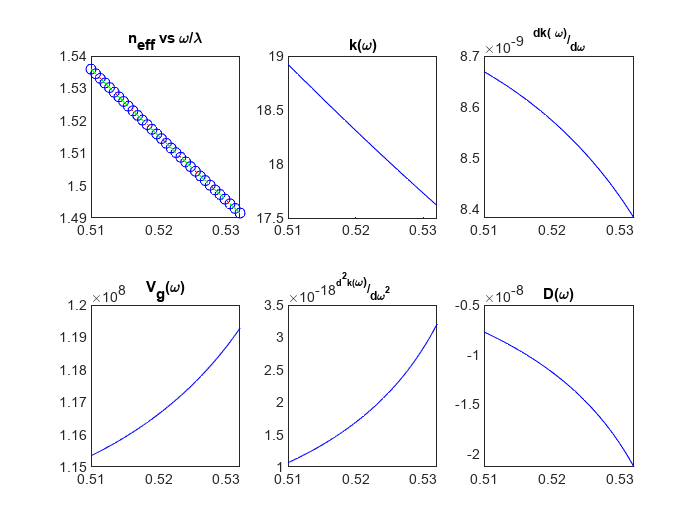

subplot(2,3,1);
plot(l,neff,'bo',l,wgSuperior.neffwFun(w),'r-.',l,wgSuperior.nefflFun(l),'g--');
title("n_{eff} vs \omega/\lambda");
subplot(2,3,2);
plot(l,wgSuperior.kwFun(w),'b');
title("k(\omega)");
subplot(2,3,3);
plot(l,wgSuperior.dkwdwFun(w),'b');
title("^{dk(\omega)}/_{d\omega}");
subplot(2,3,4);
plot(l,wgSuperior.vgwFun(w),'b');
title("V_g(\omega)");
subplot(2,3,5);
plot(l,wgSuperior.d2kwdw2Fun(w),'b');
title("^{d^2k(\omega)}/_{d\omega^2}");
subplot(2,3,6);
plot(l,wgSuperior.DwFun(w),'b');
title("D(\omega)");

##  Load Waveguide Simple:

 
file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
file = sprintf(Superior,sXs(sel),sYs(sel),mode);
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);

## K's comparing

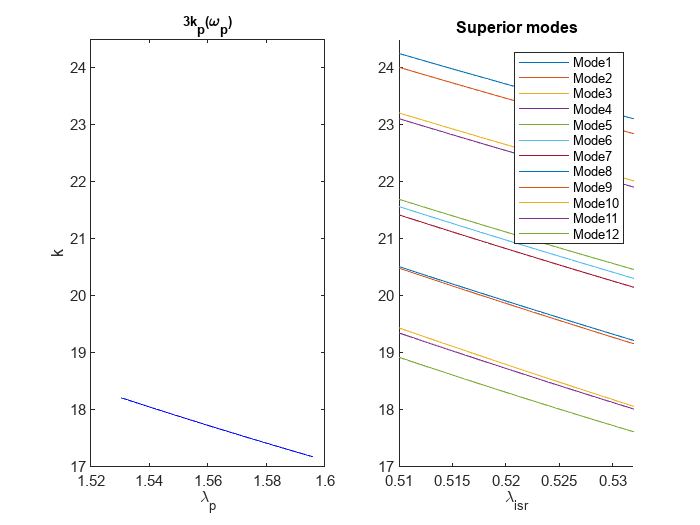

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
l = wgFundamental.lambdaData;
w = wgFundamental.omegaData;
neff = wgFundamental.neffData;
figure;
subplot(1,2,1)
plot(l,wgFundamental.kwFun(w).*3,'b');
leg = {};
title("3k_p(\omega_p)"); xlabel("\lambda_p"); ylabel("k");
ylim([17 24.5]);
subplot(1,2,2)
hold on
for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    l = wgSuperior.lambdaData;
    w = wgSuperior.omegaData;
    plot(l,wgSuperior.kwFun(w));
    leg(end+1) = {"Mode"'+num2str(i)};
end
legend(leg);
ylim([17 24.5]);
title("Superior modes"); xlabel("\lambda_{isr}");
hold off

## Find degenerate photon that allow momentum and energy conservation

size=50;

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
lp = linspace(lpLim(1),lpLim(2),size);
wp = 2.*pi.*3.*10.^8./lp;
ws = wp./3;
leg = {};

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);

figure
hold on

dk0s = [];

for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    %Nota w 10^8 es 10^14

    dk = wgSuperior.kwFun(wp)-(3*wgFundamental.kwFun(ws));

    if(min(dk)<=0 && max(dk)>=0)
        dk0s = [dk0s i];
    end

    plot(lp,dk);
    leg(end+1) = {"Mode"'+num2str(i)};
end

if ~isequal(dk0s,[])
    strDk0s = sprintf('Modo %i,',dk0s);
    strDk0s = "Modos con dK=0: "+strDk0s(1:end-1);
else
    strDk0s = "Ningun modo con dK=0";
end

disp(strDk0s)

Ningun modo con dK=0


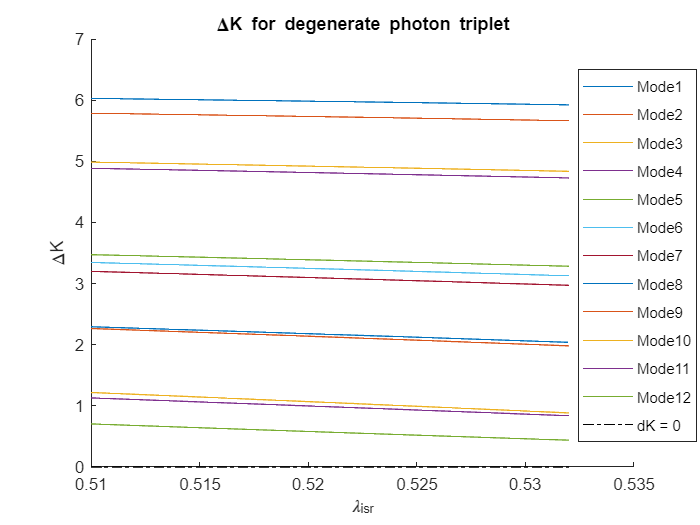


plot([lpLim(1),lpLim(2)],[0,0],'k-.')
leg(end+1) = {"dK = 0"};

legend(leg);
title("\DeltaK for degenerate photon triplet");
ylabel("\DeltaK"); xlabel("\lambda_{isr}");

legend("Position", [0.8256,0.15841,0.16964,0.70952])

## Phase Matching

switch nmodes
    case 15
        m = 5;n = 3;
    case 9
        m = 3;n = 3;
    case 19
        m = 5;n = 4;
    case 12
        m = 4;n = 3;
end

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
li = 1.53;
size=50;

wp = linspace(2.*pi.*3.*10.^8./lpLim(1),2.*pi.*3.*10.^8./lpLim(2),size);
dw = linspace(1e8,-1e8,size);
[WP,DW] = meshgrid(wp,dw);
wi = (2.*pi.*3.*10.^8./li);
wr = DW+(WP-wi)/2;
ws = WP-wi-wr;

disp("Pump wavelength: "+num2str(lpLim(1))+"-"+num2str(lpLim(2)));

Pump wavelength: 0.51-0.532


disp("Photon wavelength: "+num2str(lphLim(1))+"-"+num2str(lphLim(2)));

Photon wavelength: 1.53-1.596


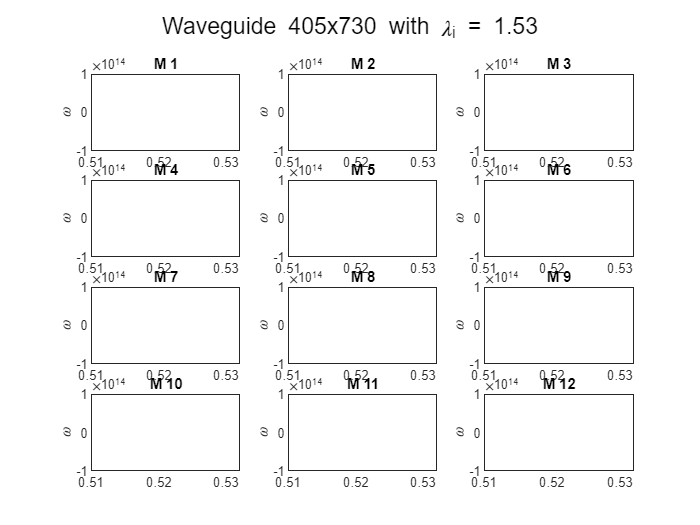

figure
for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    %Nota w 10^8 es 10^14
    DK = wgSuperior.kwFun(WP)-(wgFundamental.kwFun(wi)+wgFundamental.kwFun(wr)+wgFundamental.kwFun(ws));
    subplot(m,n,i)
    contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'b','LineWidth',2);
    title("M "+num2str(i));
    ylabel("\omega");
end
sgtitle("Waveguide "+num2str(sXs(sel))+"x"+num2str(sYs(sel))+" with \lambda_i = "+num2str(li))